# Demo for model identification from building system measurement data

[Open Live Script in Matlab](matlab:open("Demo_system_identification_nonlin.mlx"))

load data_testroom_scaled
% Initiate model
ts = 1;                             % discrete sampling time
r = 2;                              % rank of parameter tensor for approximation

% Store Data in iddata Object
dataId=iddata(x_sc(1:200,:),u_sc(1:200,:),ts,'Outputname',name(5:6),'Inputname', name(1:4),'TimeUnit','minutes');   % identification data
dataVal=iddata(x_sc(200:400,:),u_sc(200:400,:),ts,'Outputname',name(5:6),'Inputname', name(1:4),'TimeUnit','minutes');% validation data

% Estimate MTI Model from data
[sys,cost]=mlgreyest(dataId,r,"Method","fmincon","Initialize","zero","Focus","simulation");      % estimate structure and parameter matrix

identification finished: final cost: 0.84357


% Simulation for validation
x0 = dataVal.y(1,:)';                  % initial state
[~,~,xsim]=msim(sys,dataVal.u,length(dataVal.y), x0);

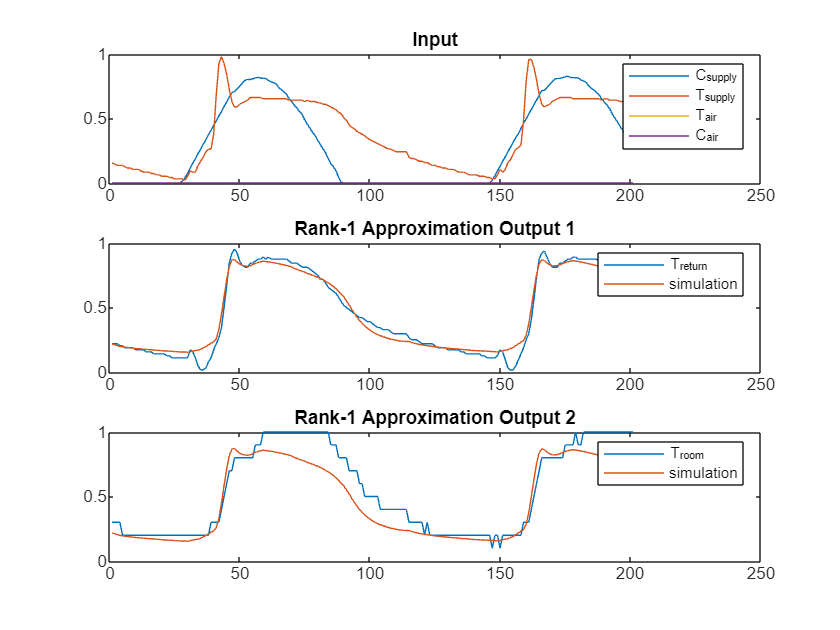


% Plot simulated vs. measured output
figure
subplot(3,1,1)
plot(dataVal.u)
legend(dataVal.Inputname)
title('Input')
subplot(3,1,2)
plot([dataVal.y(:,1) xsim(1:end-1,1)])
legend([dataVal.OutputName(1) 'simulation'])
title('Rank-1 Approximation Output 1')
subplot(3,1,3)
plot([dataVal.y(:,2) xsim(1:end-1,1)])
legend([dataVal.OutputName(2) 'simulation'])
title('Rank-1 Approximation Output 2')